TN=tencom(y,u,r,init,varargin)

------------- Tensor completion given the inputs, outputs, TT-ranks, and TT initialization with scalar inputs

y = Outputs,

u = Inputs,

r = TT-ranks,

init = TT initialization.

Reference ---------

Fast and Accurate Tensor Completion with Tensor Trains: A System Identification Approach

clear all
% load Data_mnist
% tic
% p=1
% featurez=feature{p}(1:60000, :);    tfeaturez=feature{p}(60000+1:end,:);
J=7;

filename = 'C:\Users\Ridvanz\Desktop\ThesisGit\Thesis\DATASETS\covtype';
AA = readmatrix(filename);
AA=  AA(randperm(size(AA,1))',[1:10 end])

AA =         3226          20          17         175          18        3309         206         202         129        3339           2
        2760         337           7          30           4         871         204         230         165        2164           2
        3183          65          20         424         -11         858         235         194          83        1237           2
        2423         281          14         335          56        1080         180         240         200        1448           3
        3001         309          20         408         151        5783         161         222         200        4904           2
        2621         191           9           0           0        1573         220         247         161         108           2
        3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77    

BB=[];
for ii= 1:J
    sels = find(AA(:,end)==ii,2000);
    BB = [BB ; AA(sels,:)];
end

sels =      7
     8
     9
    10
    16
    18
    21
    22
    25
    26


BB =         3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77        1113         201         188         115        3334           1
        3232         195           7         201          19        5960         219         246         162        1055           1
        2834         327          10         331          42        4184         196         229         173        5487           1
        3132         320          16         124           8        4005         177         223         185        1731           1
        3374          85           3         408          52        3355         223         234         147        1693           1
        3154         287          12          90          17        2236         186         239         193         693           1
        3179          82          12         319          88    

sels =      1
     2
     3
     5
     6
    11
    12
    15
    17
    19


BB =         3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77        1113         201         188         115        3334           1
        3232         195           7         201          19        5960         219         246         162        1055           1
        2834         327          10         331          42        4184         196         229         173        5487           1
        3132         320          16         124           8        4005         177         223         185        1731           1
        3374          85           3         408          52        3355         223         234         147        1693           1
        3154         287          12          90          17        2236         186         239         193         693           1
        3179          82          12         319          88    

sels =      4
    35
    38
    86
   122
   134
   153
   157
   163
   169


BB =         3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77        1113         201         188         115        3334           1
        3232         195           7         201          19        5960         219         246         162        1055           1
        2834         327          10         331          42        4184         196         229         173        5487           1
        3132         320          16         124           8        4005         177         223         185        1731           1
        3374          85           3         408          52        3355         223         234         147        1693           1
        3154         287          12          90          17        2236         186         239         193         693           1
        3179          82          12         319          88    

sels =          293
         308
         664
         883
        1282
        1302
        1521
        1537
        1752
        2280


BB =         3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77        1113         201         188         115        3334           1
        3232         195           7         201          19        5960         219         246         162        1055           1
        2834         327          10         331          42        4184         196         229         173        5487           1
        3132         320          16         124           8        4005         177         223         185        1731           1
        3374          85           3         408          52        3355         223         234         147        1693           1
        3154         287          12          90          17        2236         186         239         193         693           1
        3179          82          12         319          88    

sels =     32
    77
   212
   255
   286
   304
   388
   407
   485
   491


BB =         3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77        1113         201         188         115        3334           1
        3232         195           7         201          19        5960         219         246         162        1055           1
        2834         327          10         331          42        4184         196         229         173        5487           1
        3132         320          16         124           8        4005         177         223         185        1731           1
        3374          85           3         408          52        3355         223         234         147        1693           1
        3154         287          12          90          17        2236         186         239         193         693           1
        3179          82          12         319          88    

sels =     13
    53
    85
    90
   110
   113
   128
   150
   155
   160


BB =         3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77        1113         201         188         115        3334           1
        3232         195           7         201          19        5960         219         246         162        1055           1
        2834         327          10         331          42        4184         196         229         173        5487           1
        3132         320          16         124           8        4005         177         223         185        1731           1
        3374          85           3         408          52        3355         223         234         147        1693           1
        3154         287          12          90          17        2236         186         239         193         693           1
        3179          82          12         319          88    

sels =     14
    62
    71
   107
   141
   167
   189
   198
   241
   259


BB =         3193         153          17          95           3        1861         238         239         125        1549           1
        2936          23          22         150          77        1113         201         188         115        3334           1
        3232         195           7         201          19        5960         219         246         162        1055           1
        2834         327          10         331          42        4184         196         229         173        5487           1
        3132         320          16         124           8        4005         177         223         185        1731           1
        3374          85           3         408          52        3355         223         234         147        1693           1
        3154         287          12          90          17        2236         186         239         193         693           1
        3179          82          12         319          88    


% BB=


gt=(BB(:,1:10)-min(AA(:,1:10)))./(max(AA(:,1:10))-min(AA(:,1:10)));

gt =     0.6673    0.4250    0.2576    0.0680    0.2274    0.2615    0.9370    0.9409    0.4921    0.2159
    0.5388    0.0639    0.3333    0.1074    0.3230    0.1564    0.7913    0.7402    0.4528    0.4648
    0.6868    0.5417    0.1061    0.1439    0.2481    0.8374    0.8622    0.9685    0.6378    0.1471
    0.4877    0.9083    0.1515    0.2369    0.2778    0.5879    0.7717    0.9016    0.6811    0.7650
    0.6368    0.8889    0.2424    0.0888    0.2339    0.5627    0.6969    0.8780    0.7283    0.2413
    0.7579    0.2361    0.0455    0.2921    0.2907    0.4714    0.8780    0.9213    0.5787    0.2360
    0.6478    0.7972    0.1818    0.0644    0.2455    0.3142    0.7323    0.9409    0.7598    0.0966
    0.6603    0.2278    0.1818    0.2283    0.3372    0.0971    0.9331    0.8622    0.4370    0.0913
    0.6278    0.9667    0.1970    0.0608    0.2364    0.5467    0.7717    0.8622    0.6339    0.0376
    0.4977    0.6472    0.3182    0.0480    0.2429    0.5547    0.7165    0.9961    0.


inputamadre = normalize(gt);
max(abs(inputamadre))

ans =     2.6309    1.8718    4.1478    5.4317    5.8577    3.8157    6.9183    5.5960    2.9249    4.9909


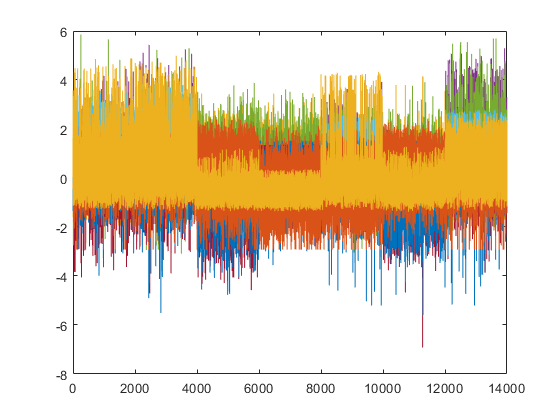

plot(inputamadre);

gt2 = (1 + exp(-1*inputamadre)).^-1;
% 2 4 6 9

beb=10

beb = 10

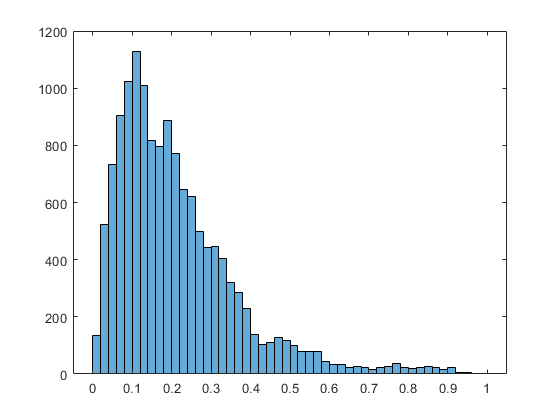

histogram(gt(:,beb))

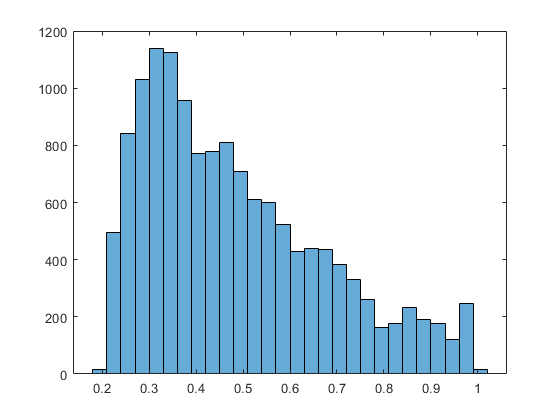

histogram(gt2(:,beb))

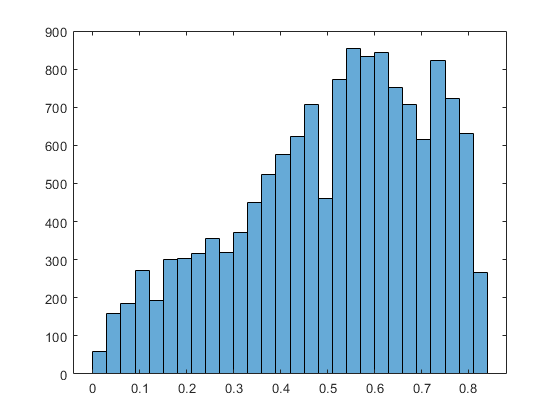

% % axis([0 1 inf inf])

gt(:,[1 3 5 7 8]) = gt2(:,[1 3 5 7 8]);

histogram(gt(:,8))

featurez=gt(1:end, :); 
tfeaturez=gt(1:end, :);
% tfeaturez=gt(60001:70000, :);
% tlabels=AA(60001:70000, end);
tlabels=BB(1:end, end);  
yt=BB(1:end, end);            

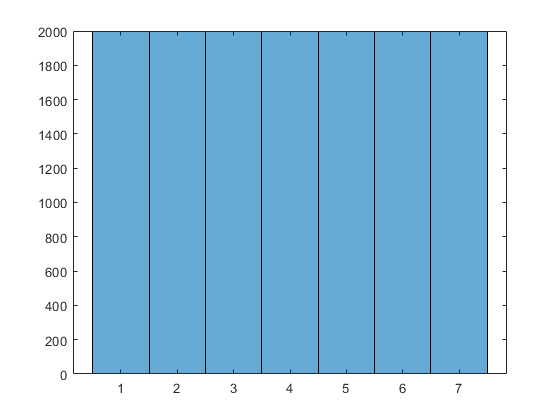

histogram(yt)


labelos=[];
for j=1:J
labelos = [labelos yt==j];
end

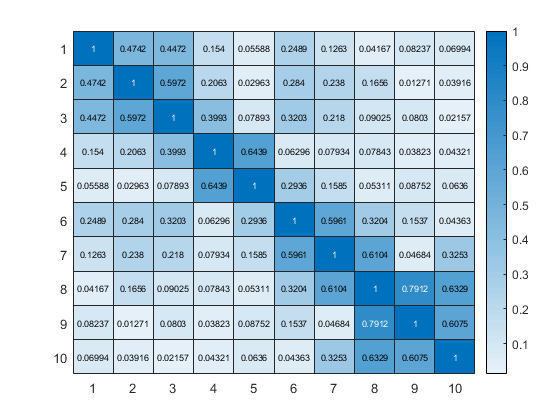


a = featurez;
Covz = corr(featurez);
Z= 1-abs(Covz);
[optima, distas] = findorder(Z);
featurez = featurez(:,optima');
Z = corr(featurez);
heatmap(abs(Z));


tfeaturez = tfeaturez(:,optima');


y = labelos(:);
[y, Id] = sort(y);
y = flipud(y);
Id = flipud(Id);

find( y==0, 1) 

ans = 14001

[N1, d1]=size(featurez); 
d=d1+1;
N=N1*J;

nn = 3;  %degree B-spline
knotintervals = 1;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (featurez/knotdist)-indexes+1;
for i=1:d1
bn = inputs(:,i).^[nn:-1:0]*M;

ub{i} = zeros(N1,nnn);
for ii=1:N1
   ub{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end


u{1} = kron(eye(J),ones(N1,1));
u{1}=u{1}(Id,:);
for i=1:d1
u{i+1} = repmat(ub{i},J,1);
u{i+1}=u{i+1}(Id,:);
end



Pcount = (nnn)^d

Pcount = 4194304

gamma=((N/Pcount^4))

gamma = 3.1666e-22

% gamma=0

R = nnn^2;
% R=6;
r=R*ones(1,d+1);
r(1) = 1; r(2)=J;    r(d-1)=nnn^2; r(d)=nnn; r(d+1)=1;

% r(3)=5;
disp(r)

     1     7    16    16    16    16    16    16    16    16     4     1




n=[J nnn*ones(1,d)];

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

res1=[];
res2=[];
MAXITR = 2*d;

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

gamma=0.00000001;
 tic
bbb=1;
% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
            
nselect = floor(((itr+1)/(MAXITR*2))^2*(N-N1));
preselect = N1+randperm((N-N1),nselect);
dataselect = [1:N1 preselect] ;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
        D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));        
        g=pinv(A'*A + gamma*D)*(A'*y(dataselect,:));
testoro(bbb) = g'*g;
bbb=bbb+1;
        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-y(dataselect,:))^2/(N1+nselect); % check residual
            res2(itr)=1*(g'*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   

        
end  

    "iteration:"    "2"    "4.2323"

    "iteration:"    "3"    "8.2025"

    "iteration:"    "4"    "12.3758"

    "iteration:"    "5"    "16.7948"

    "iteration:"    "6"    "20.7779"

    "iteration:"    "7"    "25.2826"

    "iteration:"    "8"    "29.5208"

    "iteration:"    "9"    "33.7292"

    "iteration:"    "10"    "37.9963"

    "iteration:"    "11"    "42.6742"

    "iteration:"    "12"    "47.1484"

    "iteration:"    "13"    "52.0507"

    "iteration:"    "14"    "56.9941"

    "iteration:"    "15"    "61.954"

    "iteration:"    "16"    "67.0064"

    "iteration:"    "17"    "72.2194"

    "iteration:"    "18"    "77.6836"

    "iteration:"    "19"    "83.1845"

    "iteration:"    "20"    "89.3112"

    "iteration:"    "21"    "95.5361"

    "iteration:"    "22"    "101.8161"



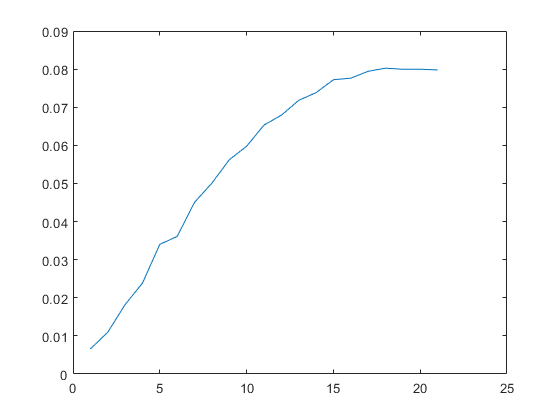

plot(res1)

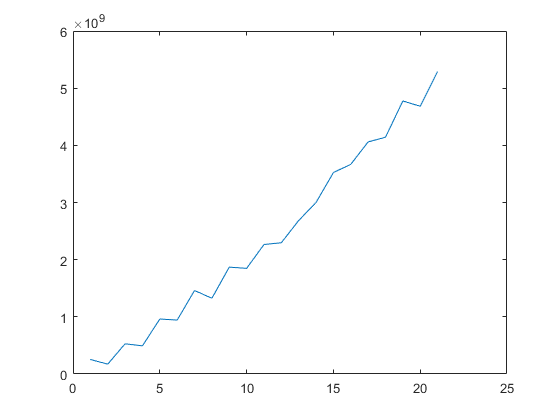

plot(res2)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;
for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 2:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i-1}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end

output= zeros(Nt,J);
V(1)= G(1);
for jj=1:Nt   
f = squeeze(V{1});
for i = 2:length(G)
f = f*V{i}(:,:,jj);
end
output(jj,:)=f';
end


[~,ind] = max(output,'',2)

ind =      7
     2
     1
     2
     1
     7
     1
     5
     1
     2


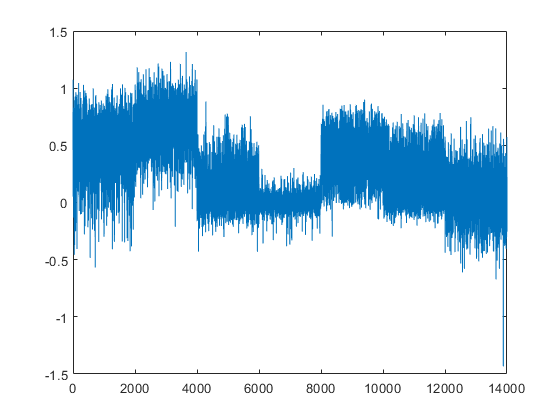

plot(output(:,2))

doedoe=202

doedoe = 202

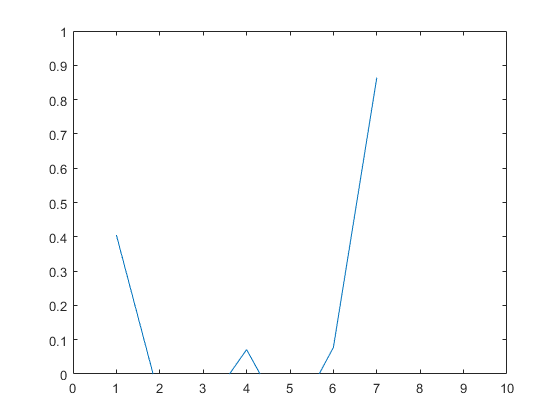

plot(output(doedoe,:))
axis([0 10 0 1])

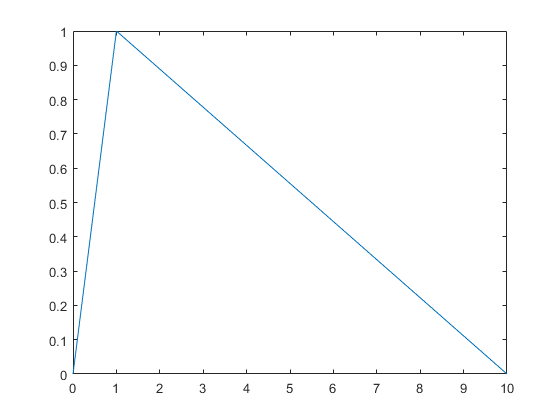

plot([0 tlabels(doedoe) 10],[0 1 0])
axis([0 10 0 1])


ind=ind

ind =      7
     2
     1
     2
     1
     7
     1
     5
     1
     2


test_err=sum(ind ~= tlabels)/10000

test_err = 0.3439

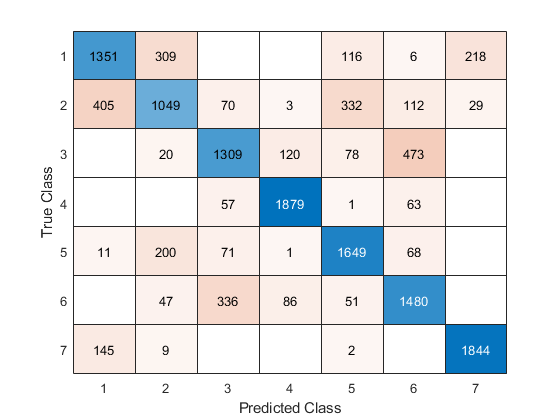


Conf = confusionmat(tlabels,ind);
confusionchart(Conf);


% % -------
% Vp=cell(1,d);
% Vm=cell(1,d);
% 
% Vm{1}=ones(N,1);
% Vp{d}=ones(N,1);
% 
% % initialize right-orthonormal cores with prescribed TN ranks
% for i=d:-1:2
%     Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
% end



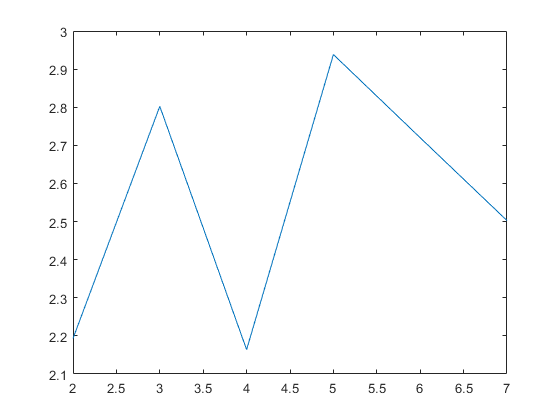


for numro=1:J

itis= (tlabels == (numro-1));
tota=sum(itis);
testlabels = (itis);
erboi = output(:,numro)-testlabels;
relerror(numro) = sum(abs(erboi))/sum(testlabels);
end

plot(relerror)


relerz = sum(abs(erboi))/10000

relerz = 0.5005

sum(testlabels)

ans = 2000

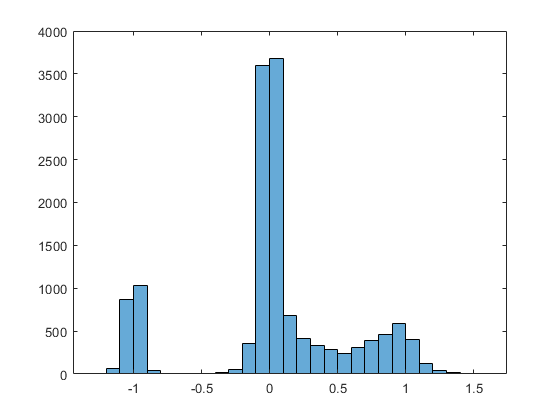

histogram((erboi)')

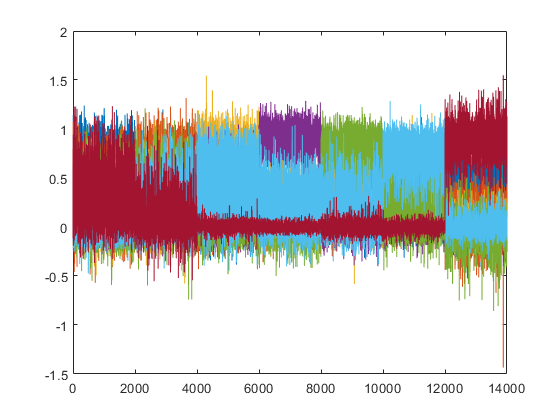


plot(output)


sum(abs(output-testlabels)<3)

ans =        14000       14000       14000       14000       14000       14000       14000



kiko = output(testlabels==10)-10


kiko =

  0×1 empty double column vector



sum(kiko<-10)

ans = 0

plot(kiko)
